# 3D Dynamics Controller

% clc
% clear all
% lengths in m
% angles in radians (3.4 degrees, 1.14 degrees)
r = 0.0054*1000;
nx = 3; % number of states
nu = 2; % number of controls
L0 = 10; % link length 1cm
% number of timesteps considered
%N = 5;
N = 31;
%N = 10;

% initial state
x0 = [0 0 0];

% goal state tries
% xref = [1.3 0.395 0.005*1000 0.015*1000];
% uref =  [0.001 0.003]*1000;
% xref = [0 0 0 0 249.06]
% uref = 1000*[-0.004 0.0019]

% ref state, control used
xref = [0 0.4813 298.8638];
u = [0.01 0.01];
uref = 1000*[0.005 -0.0025];
Xrefline = [];
Urefline = [];


Xrefline = [0 0 0;
            0 0 10;
            0 0 20;
            0 0 30;
            0 0 40;
            0 0 50;
            0 0 60;
            0 0 70;
            0 0 80;
            0 0 90;
            0 0 100;
            0 0 110;
            0 0 120;
            0 0 130;
            0 0 140;
            0 0 150;
            0 0 160;
            0 0 170;
            0 0 180;
            0 0 190;
            0 0 200;
            0 0 210;
            0 0 220;
            0 0 230;
            0 0 240;
            0 0 250;
            0 0 260;
            0 0 270;
            0 0 280;
            0 0 290;
            0 0.4813 298.8638;]';

            
for i = 1:N-2
   Urefline= [Urefline; u];
end
Urefline= [Urefline; uref]' ;

% Initial guess for states and controls
X=[];
for m = 1:N
   X= [X x0'];
end

%u_init = [0.01 0.01];
% Change the initial Control Input on line 77 
u_init = 1*[0.005 0.0025];
U = [];
for n = 1:N-1
   U = [U u_init'];
end

# Backward pass

[d_bp, K_bp, P_bp, delJ_bp] = backwardPass(X,U,Xrefline,Urefline);

# Forward pass

max(norm(d_bp));
[Xn_fp, Un_fp, Jn_fp, alpha_fp] = forwardPass(X,Urefline,Xrefline,Urefline,K_bp,d_bp,delJ_bp);

J = 4.7241e+05

Jn = 8.5692e+06

alpha_fp

alpha_fp = 0.0020

# iLQR

% atol=1e-5;
atol = 5;
d_bp = ones(nu,N-1)*10;
iter = 0;
while norm(d_bp,Inf) >  atol
    iter = iter + 1; 
    [d_bp, K_bp, P_bp, delJ_bp] = backwardPass(X,U,Xrefline,Urefline);
    max(norm(d_bp));
    [Xn_fp, Un_fp, Jn_fp, alpha_fp] = forwardPass(X,Urefline,Xrefline,Urefline,K_bp,d_bp,delJ_bp);
    X = Xn_fp;
    U = Un_fp;
end

J = 4.7241e+05

Jn = 8.5692e+06

alpha_fp

alpha_fp = 0.0020

# Plotting

figure(1)
hold on
t = linspace(1,N,N);
grid on
plot(t,Xrefline(1,:),'LineWidth',2)
plot(t,X(1,:),'LineWidth',2)
xlabel("Time Step")
ylabel("Theta")

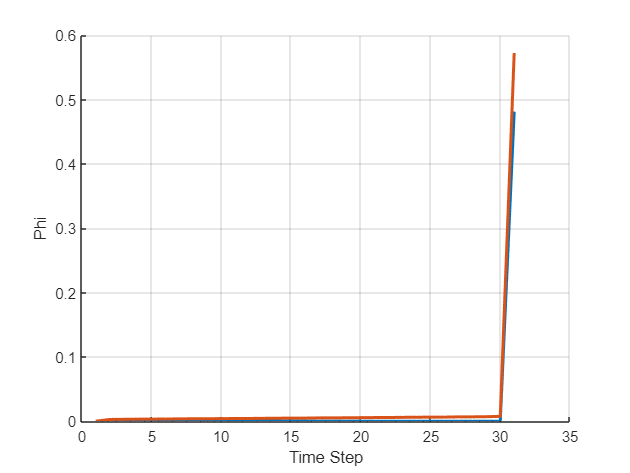

figure(2)
grid on
hold on
t = linspace(1,N,N);
plot(t,Xrefline(2,:),'LineWidth',2)
plot(t,X(2,:),'LineWidth',2)
xlabel("Time Step")
ylabel("Phi")
hold off

figure(3)
grid on
hold on
t = linspace(1,N,N);
plot(t,Xrefline(3,:),'LineWidth',2)
plot(t,X(3,:),'LineWidth',2)
xlabel("Time Step")
ylabel("L")
hold off

# Functions

function [d, K, P, delJ] = backwardPass(X,U,Xref,Uref)  % Backward Pass
    nx = 3;
    nu = 2;
    %N = 5;
    N = 31;
    %N = 10;
    
    Q = diag([100 100 1]);
    R = diag([1 1]);

    P = zeros(nx,nx,N);
    P_current = zeros(nx,nx);
    p = [];
    p_current = zeros(nx);
    d = [];
    d_current = zeros(nu);
    K = zeros(nu,nx,N-1) ; 
    K_current = zeros(nu,nx);
    delJ = 0 ; 
    delJ_current = 0;
    [P(:,:,N), p(:,N)] = term_cost_expansion(X(:,N),Xref(:,N));
    
    Jxx = zeros(nx,nx);
    Jx = zeros(nx); 
    Juu= zeros(nu,nu); 
    Ju= zeros(nu);
    Ak = [];
    Bk = [];
    Gxx = [];
    Guu = [];
    gx = [];
    gu = [];
    Gux = [];
    Gxu = [];
    
     for k = (N-1):-1:1
    
        [Jxx, Jx, Juu, Ju] = stage_cost_expansion(X(:,k),U(:,k),Xref(:,k),Uref(:,k));
        [Ak, Bk] = Jacobians(X(:,k),U(:,k));
%         cond(Ak)
%         cond(Bk)
    
        gx = Jx + Ak'*p(:,k+1);
        gu = Ju + Bk'*p(:,k+1);
    
        Gxx = Jxx + Ak'*P(:,:,k+1)*Ak;
        Guu = Juu + Bk'*P(:,:,k+1)*Bk;
        Gxu = Ak'*P(:,:,k+1)*Bk ;
        Gux = Bk'*P(:,:,k+1)*Ak;
    
        d_current = Guu\gu  ;      
        K_current = Guu\Gux;
    
        p_current = gx - K_current'*gu +K_current'*Guu*d_current - Gxu*d_current;
        P_current = Gxx + K_current'*Guu*K_current - Gxu*K_current - K_current'*Gux;
        
        p = [p p_current];
        delJ_current = gu'*d_current;
        delJ = delJ + delJ_current;
        d = [d d_current];
        K(:,:,k) = K_current;
        P(:,:,k) = P_current;
     end
end

function [Xn, Un, Jn, alpha] = forwardPass(X,U,Xref,Uref,K,d,delJ) % Forward Pass
    Xn = X;
    Un = U;
    Jn = NaN;
    %N = 5;
    N = 31;
    %N = 10;
    i = 0;
    Xn(:,1) = X(:,1);
    alpha = 1.0;
    for k = 1:(N-1)
        Un(:,k) = U(:,k) + K(:,:,k)*(Xn(:,k)-X(:,k)) + alpha*d(:,k);
        Xn(:,k+1) = Dynamics(Xn(:,k),Un(:,k));
    end
    J = trajcost(X,U,Xref,Uref)
    Jn = trajcost(Xn,Un,Xref,Uref)
    
    while isnan(Jn) || Jn > (J - 1e-2*alpha*delJ)
        alpha = 0.5*alpha;
        i = i+1;
        for k = 1:(N-1)
            Un(:,k) = U(:,k) - alpha*d(:,k) - K(:,:,k)*(Xn(:,k)-X(:,k));
            Xn(:,k+1) = Dynamics(Xn(:,k),Un(:,k));
        end
        Jn = trajcost(Xn,Un,Xref,Uref);
    end
    J = Jn;
end

%% Cost Jacobians
function [Jxx, Jx] = term_cost_expansion(x,xref)
    nx = 3;
    nu = 2;
    %N = 5;
    N = 31;
    Qf = diag([10 10 1]);
    %Qf = diag([1000 1000 10]);
    Jx = zeros(nx);
    Jx = Qf * (x-xref);
    Jxx = zeros(nx,nx);
    Jxx = Qf;
end

function [Jxx, Jx, Juu, Ju] = stage_cost_expansion(x,u,xref,uref)
    nx = 3;
    nu = 2;
    %N = 5;
    N = 31;
    Q = diag([100 100 1]);
    R = diag([1 1]);

%     Q = diag([1 1 .01]);
%     R = diag([1e-2 1e-3]);
    Jx = zeros(nx);
    Jx = Q * (x-xref);
    Ju = zeros(nu);
    Ju = R * (u-uref);
    Jxx = zeros(nx,nx);
    Jxx = Q;
    Juu = zeros(nu,nu);
    Juu = R;
end

%% Jacobian
function [A, B] = Jacobians(x, u)
    r  = 0.0054*1000;
    theta = x(1,:); phi = x(2,:); L = x(3,:);
    del_l1 = u(1,:); del_l2 = u(2,:);

    A = double([sym(1), sym(0), sym(0); (5*del_l1*sign(asin((5*del_l1)/(54*cos(theta + atan((sqrt(sym(3))*(del_l1 + 2*del_l2))/(3*del_l1))))))*sin(theta + atan((sqrt(sym(3))*(del_l1 + 2*del_l2))/(3*del_l1))))/(54*cos(theta + atan((sqrt(sym(3))*(del_l1 + 2*del_l2))/(3*del_l1)))^2*sqrt(1 - (25*del_l1^2)/(2916*cos(theta + atan((sqrt(sym(3))*(del_l1 + 2*del_l2))/(3*del_l1)))^2))), sym(1), sym(0); sym(0), -L*sin(phi), cos(phi) + sym(1)]);
    B = double([-(sqrt(sym(3))*del_l2)/(2*(del_l1^2 + del_l1*del_l2 + del_l2^2)), (sqrt(sym(3))*del_l1)/(2*(del_l1^2 + del_l1*del_l2 + del_l2^2)); (sign(asin((5*del_l1)/(54*cos(theta + atan((sqrt(sym(3))*(del_l1 + 2*del_l2))/(3*del_l1))))))*(5/(54*cos(theta + atan((sqrt(sym(3))*(del_l1 + 2*del_l2))/(3*del_l1)))) + (5*sqrt(sym(3))*del_l1*del_l2*sin(theta + atan((sqrt(sym(3))*(del_l1 + 2*del_l2))/(3*del_l1))))/(108*(sin(theta + atan((sqrt(sym(3))*(del_l1 + 2*del_l2))/(3*del_l1)))^2 - 1)*(del_l1^2 + del_l1*del_l2 + del_l2^2))))/sqrt(1 - (25*del_l1^2)/(2916*cos(theta + atan((sqrt(sym(3))*(del_l1 + 2*del_l2))/(3*del_l1)))^2)), (5*sqrt(sym(3))*sign(asin((5*del_l1)/(54*cos(theta + atan((sqrt(sym(3))*(del_l1 + 2*del_l2))/(3*del_l1))))))*sin(theta + atan((sqrt(sym(3))*(del_l1 + 2*del_l2))/(3*del_l1))))/(81*cos(theta + atan((sqrt(sym(3))*(del_l1 + 2*del_l2))/(3*del_l1)))^2*((del_l1 + 2*del_l2)^2/(3*del_l1^2) + 1)*sqrt(1 - (25*del_l1^2)/(2916*cos(theta + atan((sqrt(sym(3))*(del_l1 + 2*del_l2))/(3*del_l1)))^2))); sym(0), sym(0)]);
end

%% Dynamics
function x_next = Dynamics(x, u)
    r  = 0.0054*1000;
    L0 = 10;
    theta = x(1,:); phi = x(2,:); L = x(3,:);
    del_l1 = u(1,:); del_l2 = u(2,:);
    if del_l1 == 0 
        theta_next = theta;
        phi_next = phi;
        L_next = L + L0*cos(phi_next);
    else
        theta_next = theta + atan((sqrt(3)*(2*del_l2 + del_l1))/(3*del_l1));
        phi_next = phi + abs(asin((-del_l1)/(2*r*cos(theta_next))));
        L_next = L + L0*cos(phi_next);
    end   
    x_next = [theta_next; phi_next; L_next];
   
end

%% Cost functions
function J = stagecost(x,u,xref,uref)
    Q = diag([100 100 1]);
    R = diag([1 1]);

%     Q = diag([1 1 .01]);
%     R = diag([1e-2 1e-3]);
    J = 0.0;
    J = 0.5*(x - xref)' * Q * (x-xref) + 0.5* (u-uref)' * R * (u-uref);
end

function Jterm = termcost(x,xref)
    Qf = diag([10 10 1]);
    %Qf = diag([1000 1000 10]);
    Jterm = 0.0 ;
    Jterm = 0.5*(x - xref)' * Qf * (x-xref);
end

function Jtraj = trajcost(X,U, Xref, Uref)
    J = 0.0;
    Jnew = 0.0;
    %N = 5;
    N = 31;
    %N = 10; 
    for i = 1:(N - 1)
            Jnew = stagecost(X(:,i), U(:,i), Xref(:,i), Uref(:,i));
            J = J + Jnew;
    end
    Jtraj = J + termcost(X(:,N), Xref(:,N));
end